file = '/home/marcus/rockettrackingplatform/GazeboExport/data1';
bag = ros2bagreader(file);

msgs = readMessages(bag);

lgth = length(msgs)

lgth = 51872


for i = 1:lgth

    if msgs{i,1}.name(1) == "azimuth_joint"
        table.azimuth.position(1,i) = msgs{i,1}.position(1);
        table.azimuth.velocity(1,i) = msgs{i,1}.velocity(1);

        table.altitude.position(1,i) = msgs{i,1}.position(2);
        table.altitude.velocity(1,i) = msgs{i,1}.velocity(2);
    else
        table.altitude.position(1,i) = msgs{i,1}.position(1);
        table.altitude.velocity(1,i) = msgs{i,1}.velocity(1);

        table.azimuth.position(1,i) = msgs{i,1}.position(2);
        table.azimuth.velocity(1,i) = msgs{i,1}.velocity(2);
    end

end



% 
% adj = (table.azimuth.position(1)/(2*pi))-(floor(table.azimuth.position(1)/(2*pi)))*2*pi
% 
 for i = 1:lgth
     RadMult = table.azimuth.position(i)/(2*pi);
     RadNext = floor(table.azimuth.position(i)/(2*pi));

     rads = (RadMult - RadNext)*2*pi;

     table.azimuth.position(i) = rads;
 end

tablename = table.altitude.velocity

tablename =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000    0.0000   -1.0000   -0.0000    0.0000   -1.0000    0.0000   -0.0000   -1.0000   -0.0000   -1.0000    0.0000    0.0000   -1.0000   -0.0000   -0.0000   -1.0000    0.0000   -0.0000   -1.0000    0.0000   -1.0000   -0.0000   -0.0000   -1.0000    0.0000    0.0000   -1.0000    0.0000   -1.0000   -0.0000    0.0000   -1.0000



 [i, j, k] = find(table.azimuth.position>6.27); %Specificly Azimuth becuase it has the rotation peaks

 count = 0

count = 0

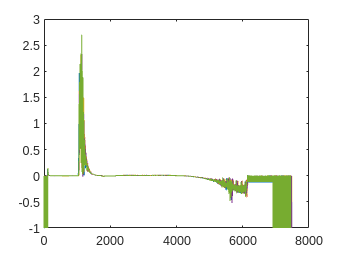


 for i = 1:length(j)
     index = i;
     if index == 18 
         index = 17;
     end
     if j(index)+1000 < j(index+1)
         count = count + 1;
         l(count) = j(index) ;
     
     end
 end

name = ["a", "b", "c", "d", "e", "f", "g"];

 for i = 1:length(l)
     try
     y.(name(i)) = tablename(l(i)+1:l(i+1)-1);
     catch
     y.(name(i)) = tablename(l(i)+1:l(end)-1);    
     end

 end
 
plot(y.a)
hold on
plot(y.b)
plot(y.c)
plot(y.d)
plot(y.e)
hold off


minlength = min([length(y.a),length(y.b),length(y.c),length(y.d),length(y.e)])

fn = fieldnames(y);
for i=1:numel(fn)  
    New(:,i) = y.(fn{i})(1:minlength)
end

New(:,6) = mean(New,2)
% count = floor(lgth/7463);
% hold on
% 
% for i = 1:count
%     xline(7463*i);
%     for j = 1:7463*i:lgth
%         table.azimuth.position(i) = table.azimuth.position(i)-2*pi*i;
%     end
% end
% 
% plot(table.azimuth.position)
% plot(table.azimuth.velocity)
% plot(table.altitude.position)
% plot(table.altitude.velocity)
% hold off